% 1
% a
num_run = 1000;
mean1 = 20;
std1 = 10;
mean2 = 30;
std2  = 10;
sample_size = 10;
group1 = normrnd(mean1, std1, [sample_size, num_run]);
group2 = normrnd(mean2, std2, [sample_size, num_run]);
[h_a, p_a, ci_a, stats_a] = ttest2(group1, group2);
sensitivity = mean(h_a)

sensitivity = 0.5600


% b
mean1 = 25;
mean2 = 25;
group1 = normrnd(mean1, std1, [sample_size, num_run]);
group2 = normrnd(mean2, std2, [sample_size, num_run]);
[h_b, p_b, ci_b, stats_b] = ttest2(group1, group2);
alpha_b = mean(h_b)

alpha_b = 0.0390


% c
alpha_4pr = 1 - (1 - alpha_b)^4

alpha_4pr = 0.1471

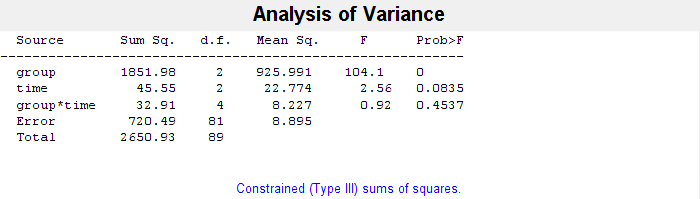

% 2
[q_g, tbl_g, stats_g, cmp_g] = anova_test_q2('group');

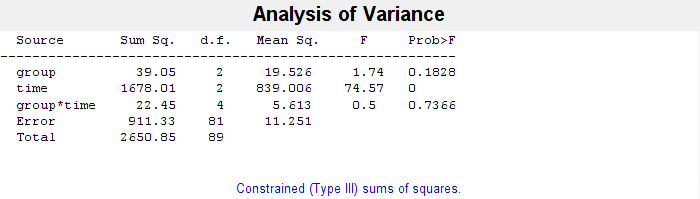

[q_t, tbl_t, stats_t, cmp_t] = anova_test_q2('time');

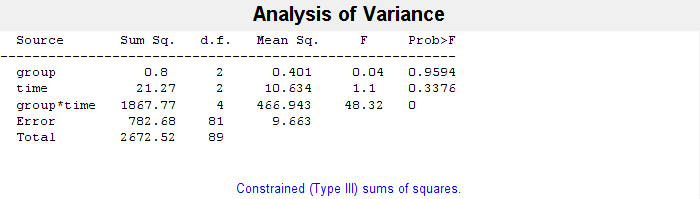

[q_i, tbl_i, stats_i, cmp_i] = anova_test_q2('interaction');

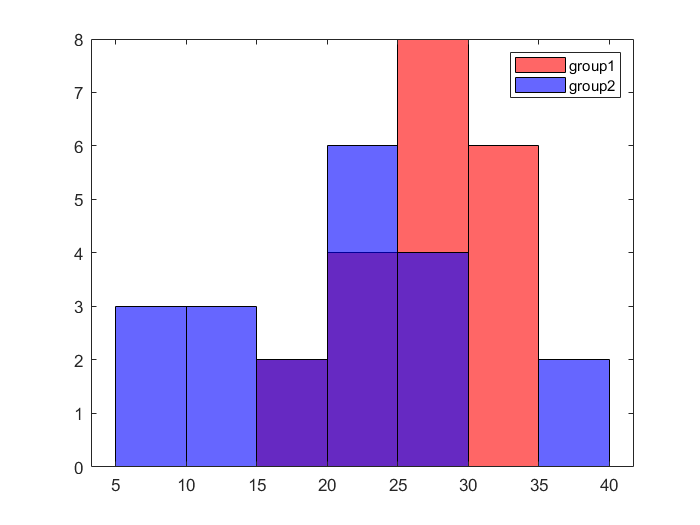

% 3
clear;
load("ps3_3.mat");
figure;
histogram(group1, 'BinWidth', 5, 'FaceColor', 'r');
hold on;
histogram(group2, 'BinWidth', 5, 'FaceColor', 'b');
legend({'group1', 'group2'});

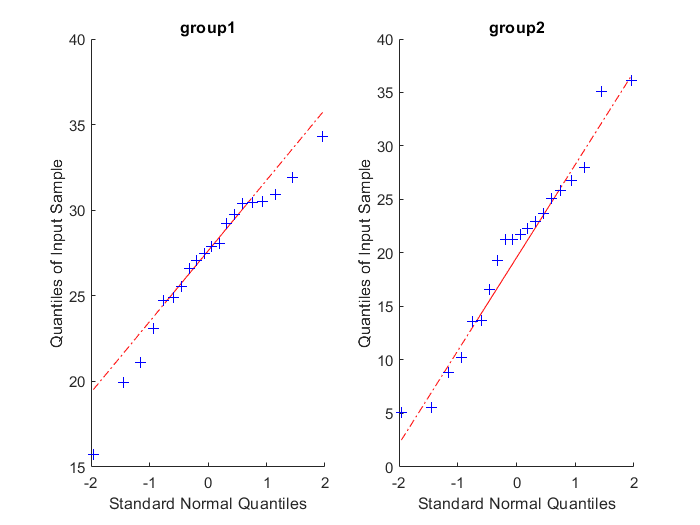


figure;
subplot(1,2,1);
qqplot(group1);
title('group1');
subplot(1,2,2);
qqplot(group2);
title('group2');

[p_3,h_3] = ranksum(group1, group2)

p_3 = 0.0040

h_3 = logical
   1


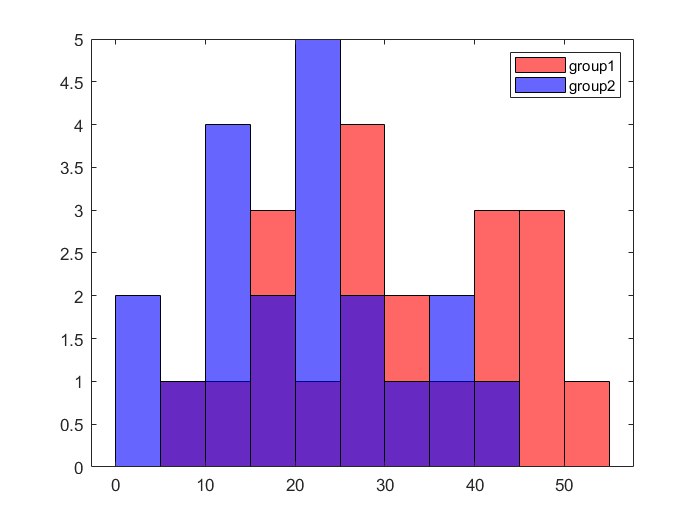

% 4
clear;
load("ps3_4.mat");
figure;
histogram(group1, 'BinWidth', 5, 'FaceColor', 'r');
hold on;
histogram(group2, 'BinWidth', 5, 'FaceColor', 'b');
legend({'group1', 'group2'});

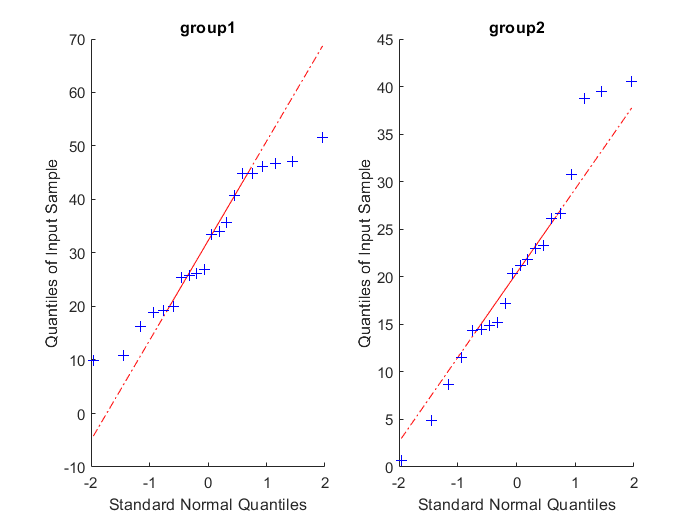


figure;
subplot(1,2,1);
qqplot(group1);
title('group1');
subplot(1,2,2);
qqplot(group2);
title('group2');


[h_4, p_4] = ttest2(group1, group2)

h_4 = 1

p_4 = 0.0085

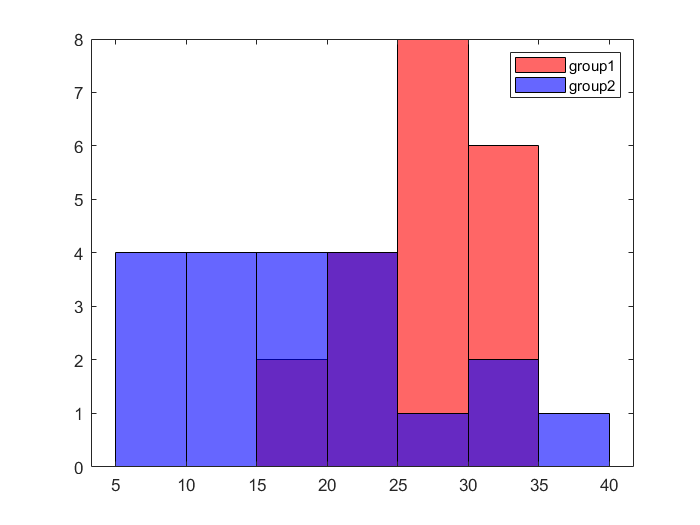

% 5
clear;
load("ps3_5.mat");
figure;
histogram(group1, 'BinWidth', 5, 'FaceColor', 'r');
hold on;
histogram(group2, 'BinWidth', 5, 'FaceColor', 'b');
legend({'group1', 'group2'});

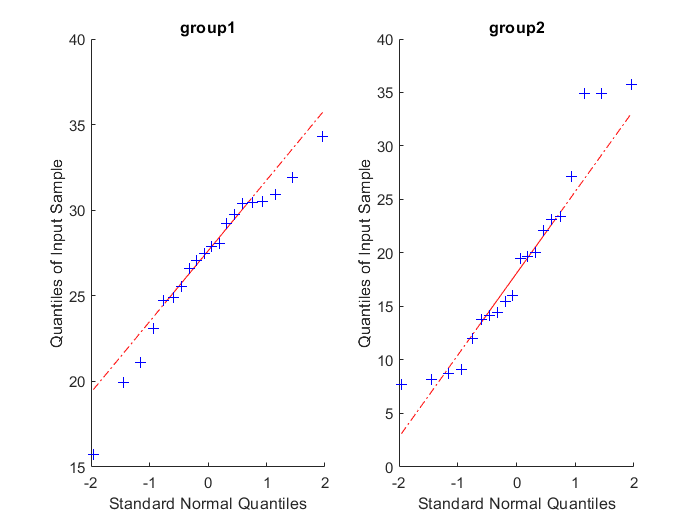


figure;
subplot(1,2,1);
qqplot(group1);
title('group1');
subplot(1,2,2);
qqplot(group2);
title('group2');


[p_5, h_5] = ranksum(group1, group2)

p_5 = 0.0020

h_5 = logical
   1


% 6
% a
clear;
load("ps3_6.mat");
stim_onset = 0.5;
% baseline spikes
baseline1 = cellfun(@(x) x(x<stim_onset), spikes1, 'UniformOutput', false);
baseline2 = cellfun(@(x) x(x<stim_onset), spikes2, 'UniformOutput', false);
% baseline firing rate, mean and variance
bsl_fr1 = cellfun(@(x) length(x)/stim_onset, baseline1);
bsl_fr2 = cellfun(@(x) length(x)/stim_onset, baseline2);
bsl_mn1 = mean(bsl_fr1)

bsl_mn1 = 4.9200

bsl_mn2 = mean(bsl_fr2)

bsl_mn2 = 0.2800

bsl_var1 = var(bsl_fr1)

bsl_var1 = 9.5037

bsl_var2 = var(bsl_fr2)

bsl_var2 = 0.4914

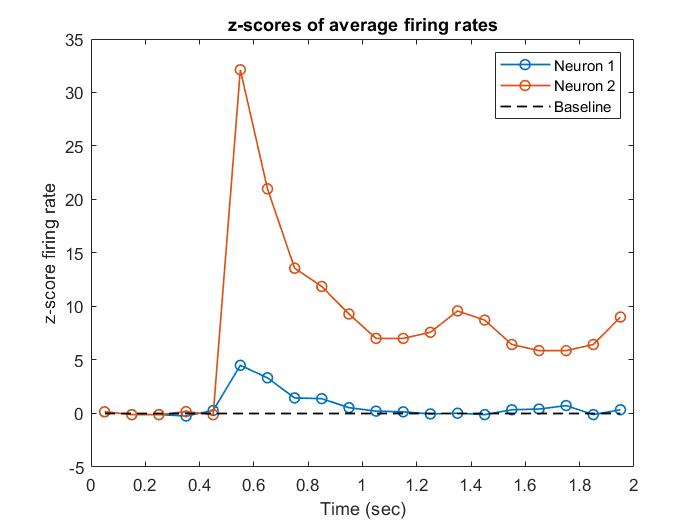


% b
bin_size = 0.1;
time_start = 0;
time_end = 2;
bin_edges = time_start:bin_size:time_end;
spikes1_bin = cellfun(@(x) histcounts(x, bin_edges), spikes1, 'UniformOutput', false);
spikes2_bin = cellfun(@(x) histcounts(x, bin_edges), spikes2, 'UniformOutput', false);
fr1_bin = mean(cell2mat(spikes1_bin)./bin_size);
fr2_bin = mean(cell2mat(spikes2_bin)./bin_size);
zs_fr1 = (fr1_bin-bsl_mn1)./sqrt(bsl_var1);
zs_fr2 = (fr2_bin-bsl_mn2)./sqrt(bsl_var2);

% plot z-score (not histogram)
bin_centers = bin_edges(1:end-1)+1/2*bin_size;
figure;
p_zs = plot(bin_centers, [zs_fr1; zs_fr2], '-o',...
    bin_centers([1,end]), [0 0], 'k--', 'LineWidth', 1);
xlabel('Time (sec)');
ylabel('z-score firing rate');
legend({'Neuron 1', 'Neuron 2','Baseline'});
title('z-scores of average firing rates');

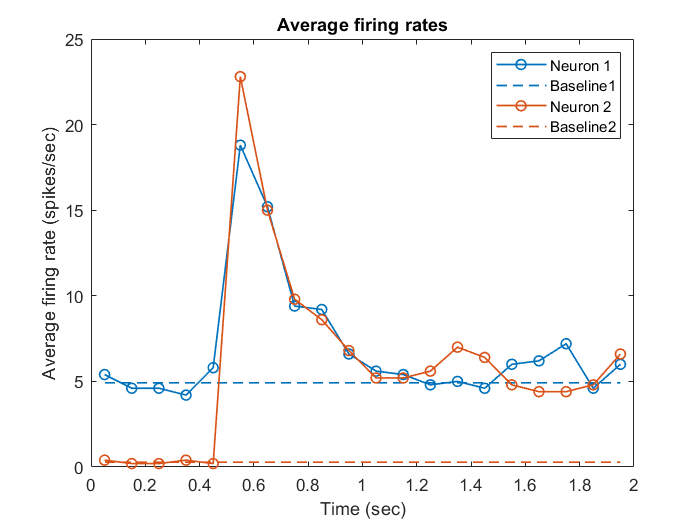


% c
% plot raw firing rate
figure;
p_raw = plot(bin_centers, fr1_bin, '-o', ...
    bin_centers([1,end]), [bsl_mn1 bsl_mn1], '--', 'Color', p_zs(1).Color, ...
    'LineWidth', 1);
hold on;
p_raw(end+1:end+2) = plot(bin_centers, fr2_bin, '-o', ...
    bin_centers([1,end]), [bsl_mn2 bsl_mn2], '--', 'Color', p_zs(2).Color, ...
    'LineWidth', 1);
xlabel('Time (sec)');
ylabel('Average firing rate (spikes/sec)');
legend({'Neuron 1', 'Baseline1', 'Neuron 2','Baseline2'});
title('Average firing rates');